%Window Method Filtering
N = 5000; %Length for Window Method

w1 = hanning(N);
w2 = hamming(N);
w3 = bartlett(N);
w4 = blackman(N);

ECGNHanning = ECGNoise.*w1;
ECGNHamming = ECGNoise.*w2;
ECGNBartlett = ECGNoise.*w3;
ECGNBlackman = ECGNoise.*w4;

ECGRHanning = ECGRandom.*w1;
ECGRHamming = ECGRandom.*w2;
ECGRBartlett = ECGRandom.*w3;
ECGRBlackman = ECGRandom.*w4;

NoiseHanningFFT = fft(ECGNHanning);
NoiseHammingFFT = fft(ECGNHamming);
NoiseBartlettFFT = fft(ECGNBartlett);
NoiseBlackmanFFT = fft(ECGNBlackman);

RandomHanningFFT = fft(ECGRHanning);
RandomHammingFFT = fft(ECGRHamming);
RandomBartlettFFT = fft(ECGRBartlett);
RandomBlackmanFFT = fft(ECGRBlackman);

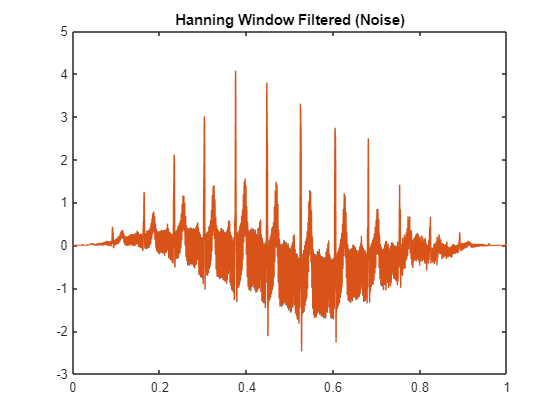

figure;
plot(t,ECGNHanning); title('Hanning Window Filtered (Noise)');

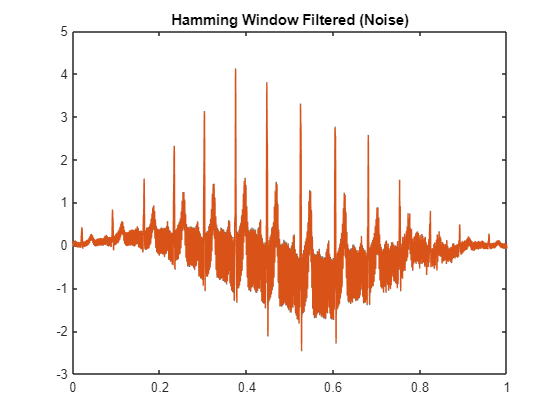


figure;
plot(t,ECGNHamming); title('Hamming Window Filtered (Noise)');

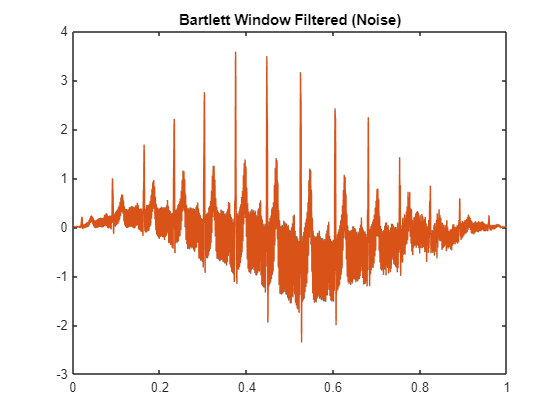


figure;
plot(t,ECGNBartlett); title('Bartlett Window Filtered (Noise)');

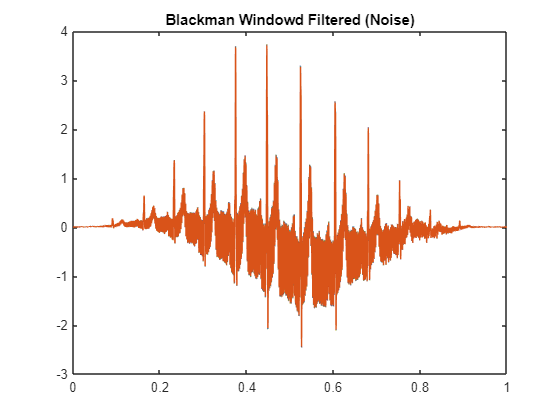


figure;
plot(t,ECGNBlackman); title('Blackman Windowd Filtered (Noise)');

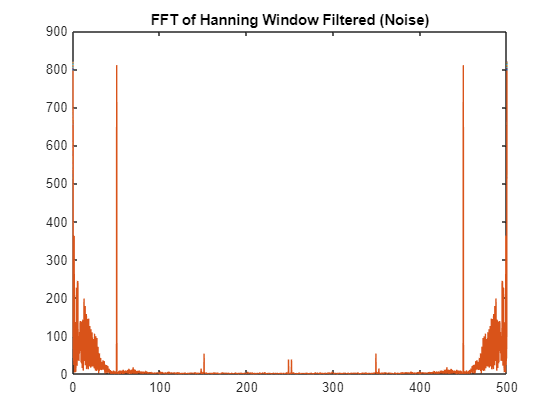

figure;
plot(f,abs(NoiseHanningFFT)); title('FFT of Hanning Window Filtered (Noise)');

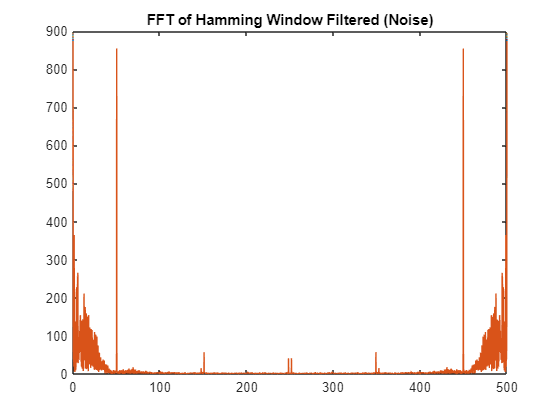


figure;
plot(f,abs(NoiseHammingFFT)); title('FFT of Hamming Window Filtered (Noise)');

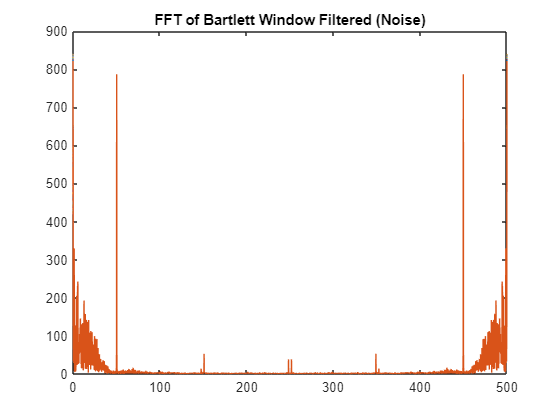


figure;
plot(f,abs(NoiseBartlettFFT)); title('FFT of Bartlett Window Filtered (Noise)');

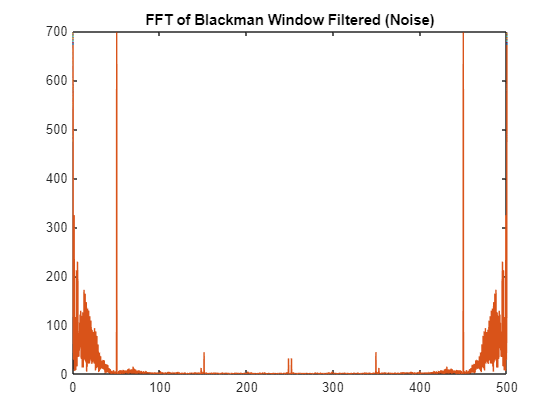


figure;
plot(f,abs(NoiseBlackmanFFT)); title('FFT of Blackman Window Filtered (Noise)');

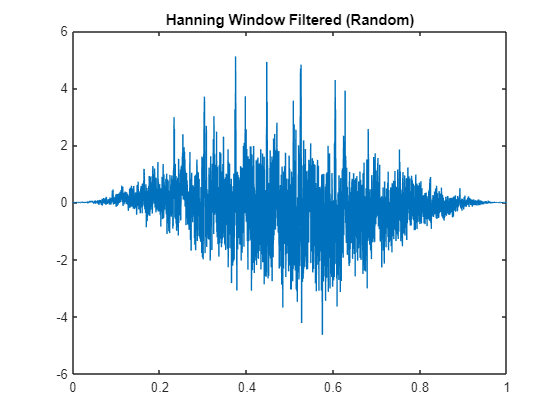

figure;
plot(t,ECGRHanning); title('Hanning Window Filtered (Random)');

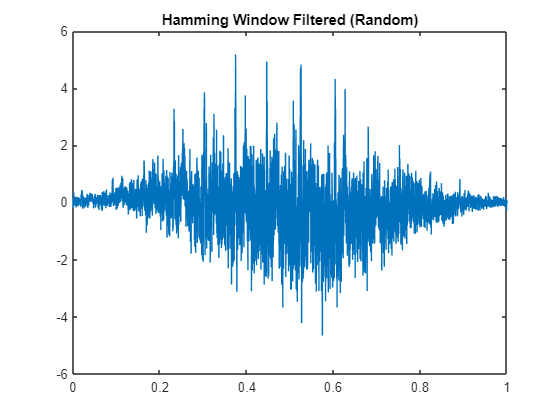


figure;
plot(t,ECGRHamming); title('Hamming Window Filtered (Random)');

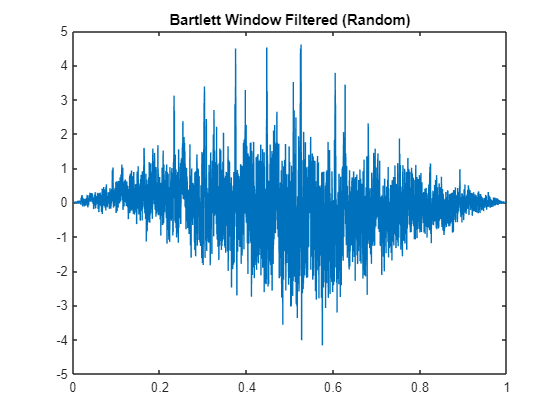


figure;
plot(t,ECGRBartlett); title('Bartlett Window Filtered (Random)');

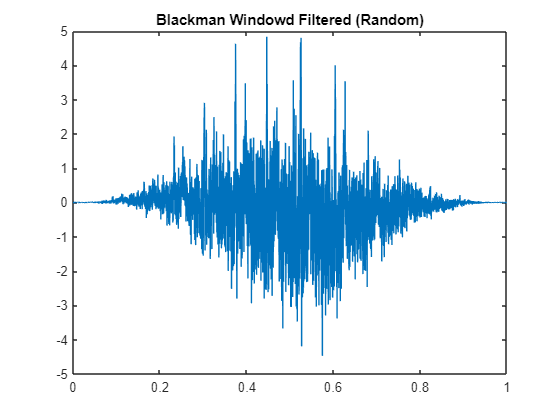


figure;
plot(t,ECGRBlackman); title('Blackman Windowd Filtered (Random)');

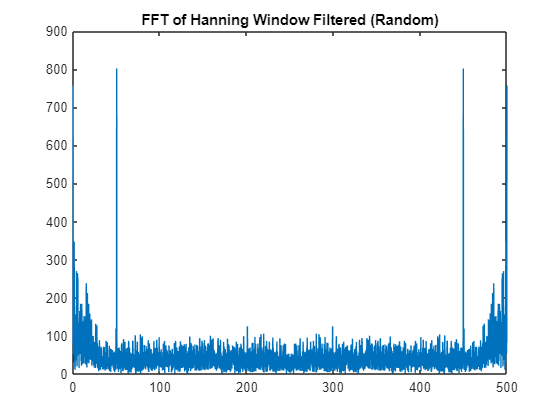


figure;
plot(f,abs(RandomHanningFFT)); title('FFT of Hanning Window Filtered (Random)');

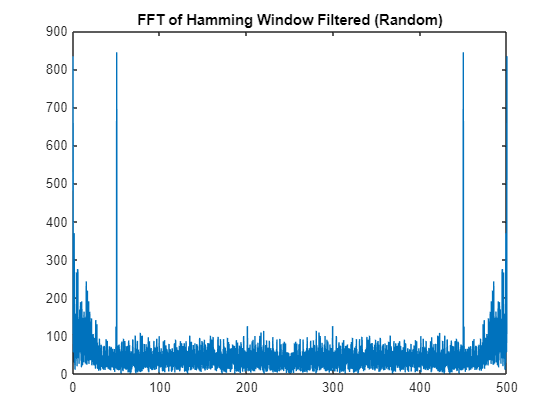


figure;
plot(f,abs(RandomHammingFFT)); title('FFT of Hamming Window Filtered (Random)');

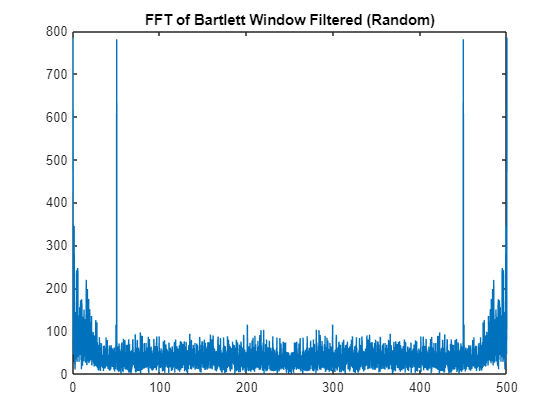


figure;
plot(f,abs(RandomBartlettFFT)); title('FFT of Bartlett Window Filtered (Random)');


figure;
plot(f,abs(RandomBlackmanFFT)); title('FFT of Blackman Window Filtered (Random)');

%for analysis

%from noisy signal
figure;
plot(f,abs(NoiseHammingFFT)) ; hold on; plot(f,abs(NoiseHanningFFT)); hold off; title('Hamming vs Hanning');
figure;
plot(f,abs(NoiseHammingFFT)); hold on; plot(f,abs(NoiseBartlettFFT)); hold off; title('Hamming vs Bartlett');
figure;
plot(f,abs(NoiseHammingFFT)); hold on; plot(f,abs(NoiseBlackmanFFT)); hold off; title('Hamming vs Blackman');


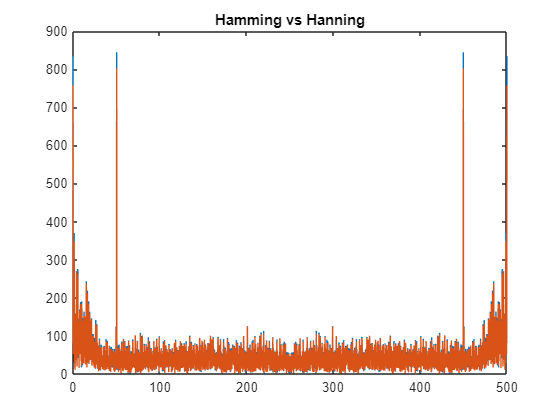

%from random noisy
figure;
plot(f,abs(RandomHammingFFT)) ; hold on; plot(f,abs(RandomHanningFFT)); hold off; title('Hamming vs Hanning');

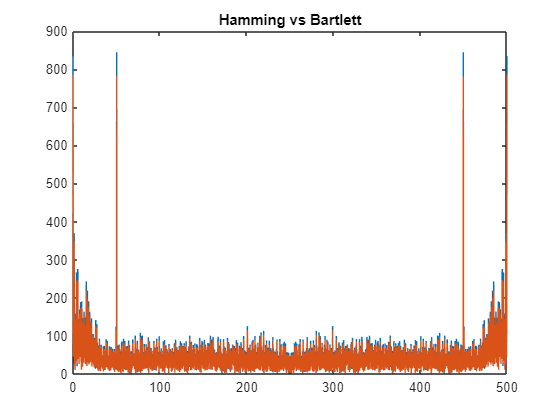

figure;
plot(f,abs(RandomHammingFFT)); hold on; plot(f,abs(RandomBartlettFFT)); hold off; title('Hamming vs Bartlett');

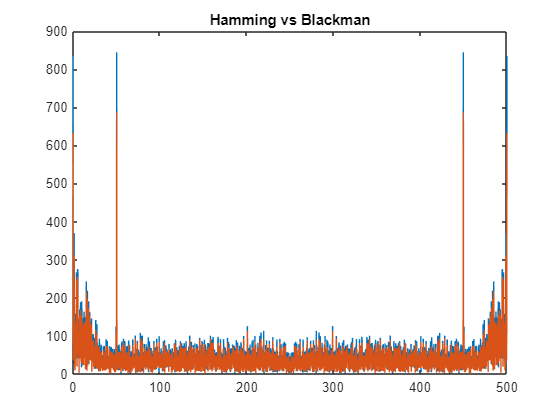

figure;
plot(f,abs(RandomHammingFFT)); hold on; plot(f,abs(RandomBlackmanFFT)); hold off; title('Hamming vs Blackman');